# Mean Square Displacement Analysis

clear;
clc;

## Wild Type

WT = "/Users/Priya/testoutput/TestMammaryMonolayerWT/results_from_time_0/velocity.dat";
[xDeltaSq, yDeltaSq, zDeltaSq,totalMSD, sum] = MSD(WT);
time = double(importfile_time(WT));

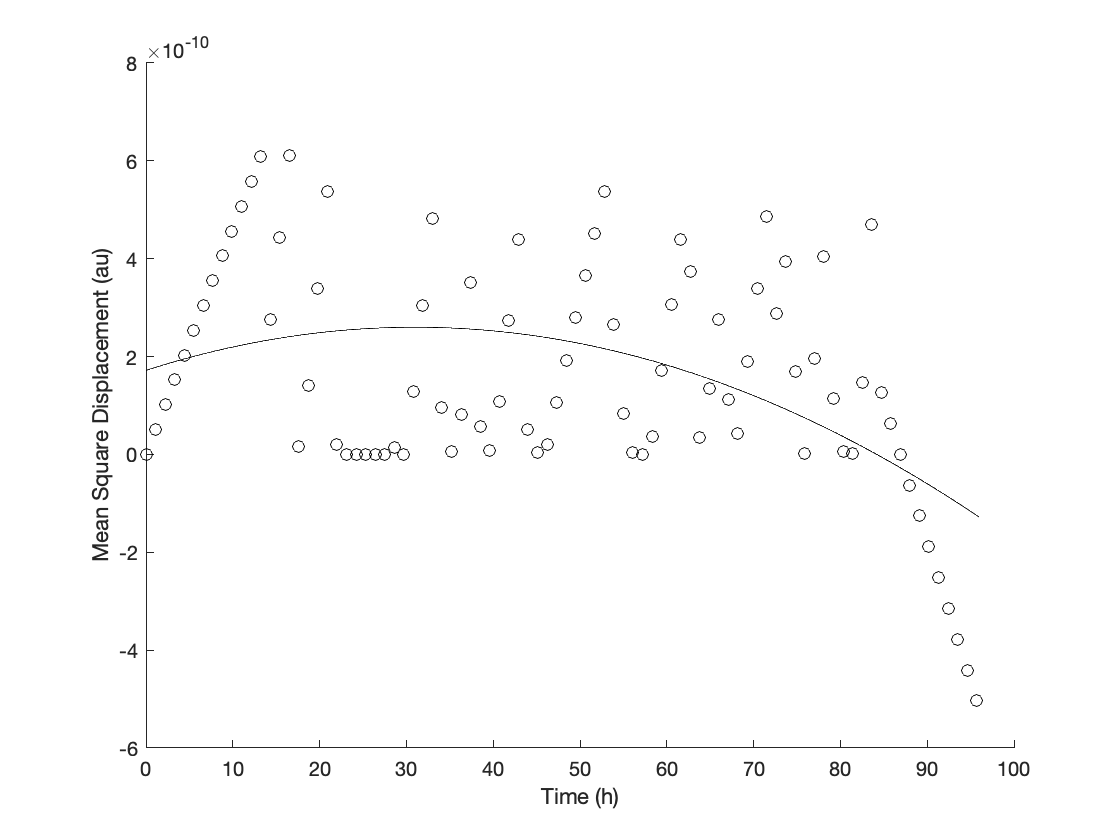

x = time(:,1);
yMSD = totalMSD(:,1);
BWT = filloutliers(yMSD,'linear','grubbs');

figure
hold on

scatter(x(1:11:960),BWT(1:11:960),'k')
pWT = polyfit(x,BWT,2);
fWT = polyval(pWT,x);
plot(x,fWT, 'k');

hold off

% title ("Total Mean Square Displacement")
xlabel("Time (h)")
ylabel("Mean Square Displacement (au)")